# Linear Regression

## Introduction

load accidents
x = hwydata(:,14); %Population of states
y = hwydata(:,4); %Accidents per state
format long
b1 = x\y;
yCalc1 = b1*x;
scatter(x,y)
hold on
plot(x,yCalc1)
xlabel('Population of state')
ylabel('Fatal traffic accidents per state')
title('Linear Regression Relation Between Accidents & Population')
legend('Data','Linear regression')
grid on
hold off

# SVD visualization

M = [0.5, 1; 0.5, 0.5];
[U, S, V] = svd(M)

U =   -0.850650808352040  -0.525731112119134
  -0.525731112119133   0.850650808352040


S =    1.309016994374947                   0
                   0   0.190983005625053


V =   -0.525731112119134   0.850650808352040
  -0.850650808352040  -0.525731112119134



subplot(2,3,1)
plot([0 0], [0 1], 'r', 'LineWidth',3)
hold on
xlim([-1.5,1.5])
ylim([-1.5,1.5])
plot([0 1], [0 0], 'b', 'LineWidth',3)

subplot(2,3,2)
v1 = M*[0;1]

v1 =    1.000000000000000
   0.500000000000000


v2 = M*[1;0]

v2 =    0.500000000000000
   0.500000000000000


plot([0 v1(1)], [0 v1(2)], 'r', 'LineWidth',3)
hold on
xlim([-1.5,1.5])
ylim([-1.5,1.5])
plot([0 v2(1)], [0 v2(2)], 'b', 'LineWidth',3)
hold off

subplot(2,3,4)
v1 = V'*[0;1]

v1 =   -0.850650808352040
  -0.525731112119134


v2 = V'*[1;0]

v2 =   -0.525731112119134
   0.850650808352040


plot([0 v1(1)], [0 v1(2)], 'r', 'LineWidth',3)
hold on
xlim([-1.5,1.5])
ylim([-1.5,1.5])
plot([0 v2(1)], [0 v2(2)], 'b', 'LineWidth',3)
hold off

subplot(2,3,5)
v1 = S*V'*[0;1]*S(1,1)

v1 =   -1.457611844529399
  -0.131432778029783


v2 = S*V'*[1;0]*S(2,2)

v2 =   -0.131432778029783
   0.031027070086670


plot([0 v1(1)], [0 v1(2)], 'r', 'LineWidth',3)
hold on
xlim([-1.5,1.5])
ylim([-1.5,1.5])
plot([0 v2(1)], [0 v2(2)], 'b', 'LineWidth',3)
hold off

subplot(2,3,6)
v1 = U*S*V'*[0;1]

v1 =    0.999999999999999
   0.500000000000000


v2 = U*S*V'*[1;0]

v2 =    0.500000000000000
   0.500000000000000


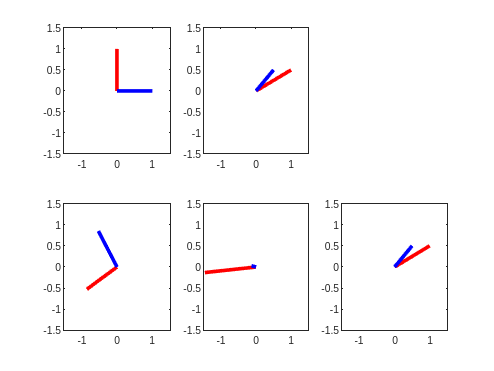

plot([0 v1(1)], [0 v1(2)], 'r', 'LineWidth',3)
hold on
xlim([-1.5,1.5])
ylim([-1.5,1.5])
plot([0 v2(1)], [0 v2(2)], 'b', 'LineWidth',3)
hold off